## **Third-order ODE:**

y''' + y'' + y' + y = 2x - 1, y(0) = 1, y'(0) = 0, y''(0) = 0

**Exact solution:**

y(x) = 2 x + 2 e^(-x) + 2 cos(x) - 3

% Define the ODE and its initial conditions
f = @(x, y) [y(2); y(3); -y(1)-y(2)-y(3)+2*x-1];
y0 = [1; 0; 0];

% Define the exact solution
y_exact = @(x) 2*x + 2*exp(-x) + 2*cos(x) - 3;

% Define the time interval and step size
t_start = 0;
t_end = 10000;
h = 0.1;
tspan = t_start:h:t_end;

% Use Forward Euler method to approximate the solution
tic
y_forward = zeros(length(y0), length(tspan));
y_forward(:,1) = y0;
for i = 2:length(tspan)
    y_forward(:,i) = y_forward(:,i-1) + h * f(tspan(i-1), y_forward(:,i-1));
end
time_forward = toc * 1000 ;

% Use Backward Euler method to approximate the solution
tic
y_backward = zeros(length(y0), length(tspan));
y_backward(:,1) = y0;
for i = 2:length(tspan)
    y_backward(:,i) = (eye(length(y0)) - h * [0, 1, 0; 0, 0, 1; -1, -1, -1]) \ ...
        (y_backward(:,i-1) + h * [0; 0; 2*tspan(i-1)-1]);
    %y_backward(:,i) = y_backward(:,i-1) + h * f(tspan(i), y_backward(:,i));
end
time_backward = toc * 1000;

y_exact(tspan)

ans = 1.0e+04 *

    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0005    0.0005    0.0006    0.0006    0.0006    0.0007    0.0007


y_forward

y_forward = 1.0e+216 *

    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
         0         0   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0

y_backward

y_backward = 1.0e+04 *

    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0006    0.0006    0.0006    0.0007
         0   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0


% Calculate the error between the exact and approximate solutions
error_forward = abs(y_exact(tspan) - y_forward(1,:))

error_forward = 1.0e+216 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


error_backward = abs(y_exact(tspan) - y_backward(1,:))

error_backward =          0    0.0015    0.0044    0.0084    0.0132    0.0184    0.0237    0.0290    0.0338    0.0381    0.0417    0.0444    0.0461    0.0468    0.0464    0.0449    0.0424    0.0389    0.0344    0.0292    0.0233    0.0170    0.0104    0.0037    0.0028    0.0090    0.0145    0.0192    0.0227    0.0250    0.0257    0.0246    0.0216    0.0164    0.0091    0.0007    0.0128    0.0275    0.0447    0.0643    0.0864    0.1107    0.1373    0.1658    0.1961    0.2280    0.2611    0.2952    0.3299    0.3648



% Error per
per_error_arr_fe = abs(error_forward ./ y_exact(tspan) * 100)

per_error_arr_fe = 1.0e+214 *

         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


per_error_arr_be = abs(error_backward ./ y_exact(tspan) * 100)

per_error_arr_be =          0    0.1484    0.4427    0.8501    1.3434    1.9004    2.5033    3.1377    3.7911    4.4519    5.1079    5.7450    6.3453    6.8851    7.3328    7.6466    7.7742    7.6548    7.2279    6.4502    5.3207    3.9038    2.3343    0.7900    0.5591    1.5980    2.2848    2.6391    2.7154    2.5791    2.2915    1.9032    1.4527    0.9683    0.4696    0.0300    0.5214    0.9988    1.4583    1.8978    2.3158    2.7118    3.0853    3.4363    3.7648    4.0711    4.3551    4.6171    4.8572    5.0753



% Mean Error Per
mean_error_fe = mean(per_error_arr_fe(2:end))

mean_error_fe = 1.4921e+211

mean_error_be = mean(per_error_arr_be(2:end))

mean_error_be = 0.0446

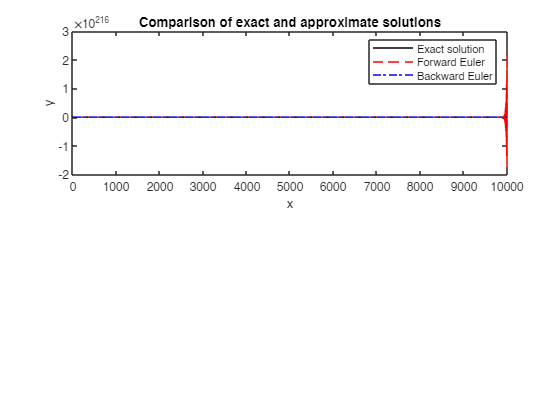


% Plot the results
figure
subplot(2,1,1)
plot(tspan, y_exact(tspan), 'k-', tspan, y_forward(1,:), 'r--', tspan, y_backward(1,:), 'b-.')
title('Comparison of exact and approximate solutions')
legend('Exact solution', 'Forward Euler', 'Backward Euler')
xlabel('x')
ylabel('y')


% Print the time taken for each method
fprintf('Time taken for Forward Euler method: %f seconds\n', time_forward);

Time taken for Forward Euler method: 202.557000 seconds


fprintf('Time taken for Backward Euler method: %f seconds\n', time_backward);

Time taken for Backward Euler method: 554.834500 seconds


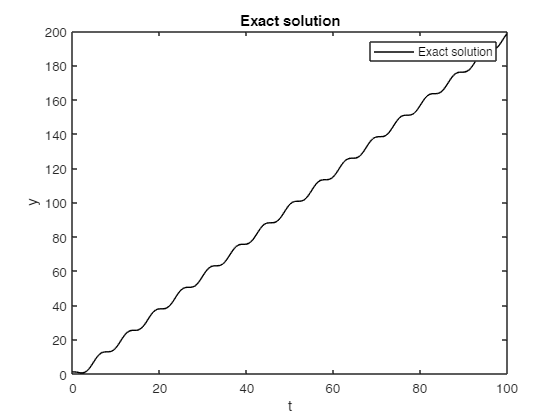

figure;
plot(tspan, y_exact(tspan), 'black-');
xlabel('t');
ylabel('y');
legend('Exact solution');
title('Exact solution');